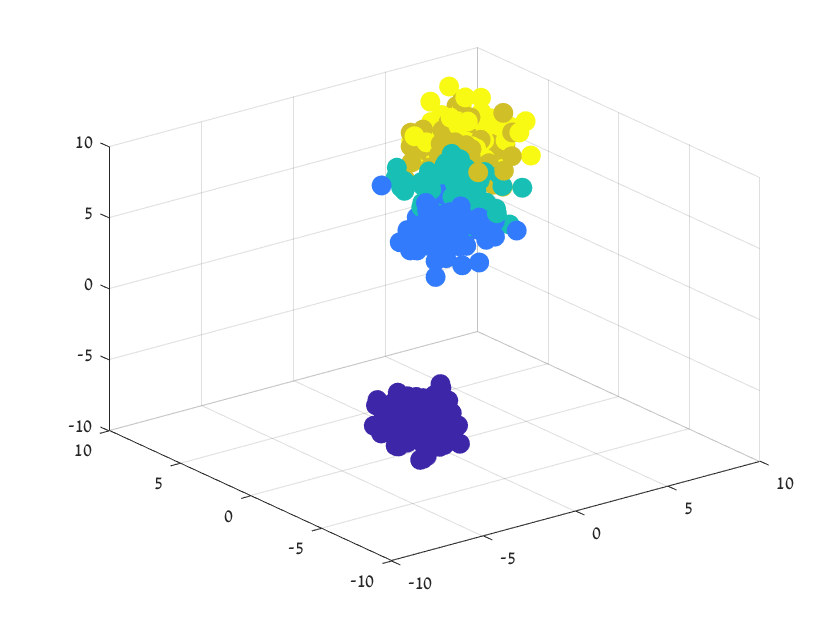

N  = 100;
D  = 10;
C  = 5;
mX = [];
vY = [];
for cc = 1 : C
   mXc = randn(D, N) + 1.5*cc;
   if cc == 1
      mXc = mXc - 6;
   end
   
   if cc == 5
      mXc = mXc - 1;
   end
   
   vYc = cc * ones(N, 1);
   mX  = cat(2, mX, mXc);
   vY  = [vY;
          vYc];
end

figure; scatter3(mX(1,:), mX(2,:), mX(3,:), 100, vY, 'Fill');


Data = [vY';
        mX];
    
rand_Data  = Data(:, randperm(size(Data,2)));
train_Data = rand_Data(:,1:450);
test_data  = rand_Data(:,451:500);